# Franka Emika Panda Singularities Set 3

clc; clear; close;

#### Define the transformation matrices for the Franka Emika Panda Robot / Configuration1

M = [[1, 0, 0, 0.088];[0, -1, 0, 0];[0, 0, -1, 0.926];[0, 0, 0, 1]];
vpa(M, 4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0.088\\ 0 & -1.0 & 0 & 0\\ 0 & 0 & -1.0 & 0.926\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

S = [[0;0;1;0;0;0],[0;1;0;-0.333;0;0],[0;0;1;0;0;0],[0;-1;0;0.316+0.333;0;-0.0825],[0;0;1;0;0;0],[0;-1;0;0.384+0.316+0.333;0;0],[0;0;-1;0;0.088;0]];
vpa(S, 4)

$$ans = \left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1.0 & 0 & -1.0 & 0 & -1.0 & 0\\ 1.0 & 0 & 1.0 & 0 & 1.0 & 0 & -1.0\\ 0 & -0.333 & 0 & 0.649 & 0 & 1.033 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0.088\\ 0 & 0 & 0 & -0.0825 & 0 & 0 & 0 \end{array}\right)$$

#### Defining joint limits 

qlim = [-2.8973, 2.8973; -1.7628, 1.7628; -2.8973, 2.8973; -3.0718, -0.0698; -2.8973, 2.8973; -0.0175, 3.7525; -2.8973, 2.8973];

vpa(qlim, 5)

$$ans = \left(\begin{array}{cc} -2.8973 & 2.8973\\ -1.7628 & 1.7628\\ -2.8973 & 2.8973\\ -3.0718 & -0.0698\\ -2.8973 & 2.8973\\ -0.0175 & 3.7525\\ -2.8973 & 2.8973 \end{array}\right)$$

#### Generate a set of discrete joint angles within the joint limits

for i=1:size(qlim, 1)
    Qlim(i, :) = linspace(qlim(i, 1), qlim(i, 2), 10);
end
Qlim

Qlim =    -2.8973   -2.2535   -1.6096   -0.9658   -0.3219    0.3219    0.9658    1.6096    2.2535    2.8973
   -1.7628   -1.3711   -0.9793   -0.5876   -0.1959    0.1959    0.5876    0.9793    1.3711    1.7628
   -2.8973   -2.2535   -1.6096   -0.9658   -0.3219    0.3219    0.9658    1.6096    2.2535    2.8973
   -3.0718   -2.7382   -2.4047   -2.0711   -1.7376   -1.4040   -1.0705   -0.7369   -0.4034   -0.0698
   -2.8973   -2.2535   -1.6096   -0.9658   -0.3219    0.3219    0.9658    1.6096    2.2535    2.8973
   -0.0175    0.4014    0.8203    1.2392    1.6581    2.0769    2.4958    2.9147    3.3336    3.7525
   -2.8973   -2.2535   -1.6096   -0.9658   -0.3219    0.3219    0.9658    1.6096    2.2535    2.8973


#### Finding $\theta_4$ for this singular configuration set.

a1 = 0; a2 = 0; a3 = 0; a4 = 0.0825;
a5 = -0.0825; a6 = 0; a7 = 0.088; aF = 0;
d1 = 0.333; d2 = 0; d3 = 0.316; d4 = 0;
d5 = 0.384; d6 = 0; d7 = 0; dF = 0.107;

th4 = atan((a5*(d3+d5))/(-a5^2 +d5*d3));
th4 = vpa(th4,10)

$$th4 = -0.4670024237$$

#### Define Singular Configurations (Define all possible configs for this set of solution)

Q1 = Qlim(1, :);
Q2 = Qlim(2, :);
Q3 = Qlim(3, :);
Q4 = [th4];
Q5 = [0];
Q6 = Qlim(6, :);
Q7 = Qlim(7, :);

#### Generate all possible combinations of joint angles for the robot

Q = unique(combvec(Q1, Q2, Q3, Q4, Q5, Q6, Q7)', 'rows');
Q

Q =    -2.8973   -1.7628   -2.8973   -0.4670         0   -0.0175   -2.8973
   -2.8973   -1.7628   -2.8973   -0.4670         0   -0.0175   -2.2535
   -2.8973   -1.7628   -2.8973   -0.4670         0   -0.0175   -1.6096
   -2.8973   -1.7628   -2.8973   -0.4670         0   -0.0175   -0.9658
   -2.8973   -1.7628   -2.8973   -0.4670         0   -0.0175   -0.3219
   -2.8973   -1.7628   -2.8973   -0.4670         0   -0.0175    0.3219
   -2.8973   -1.7628   -2.8973   -0.4670         0   -0.0175    0.9658
   -2.8973   -1.7628   -2.8973   -0.4670         0   -0.0175    1.6096
   -2.8973   -1.7628   -2.8973   -0.4670         0   -0.0175    2.2535
   -2.8973   -1.7628   -2.8973   -0.4670         0   -0.0175    2.8973


#### Remove duplicate joint angles

uniqueQ = unique(Q, 'rows');
numDuplicates = size(Q,1) - size(uniqueQ,1)

numDuplicates = 0

####  Compute the forward kinematics for each unique set of joint angles

for i = 1:size(uniqueQ,1)
    T1 = FK_SpaceForm(S, M, uniqueQ(i, 1: 7)');
    X(i) = T1(1, 4);
    Y(i) = T1(2, 4);
    Z(i) = T1(3, 4);
end

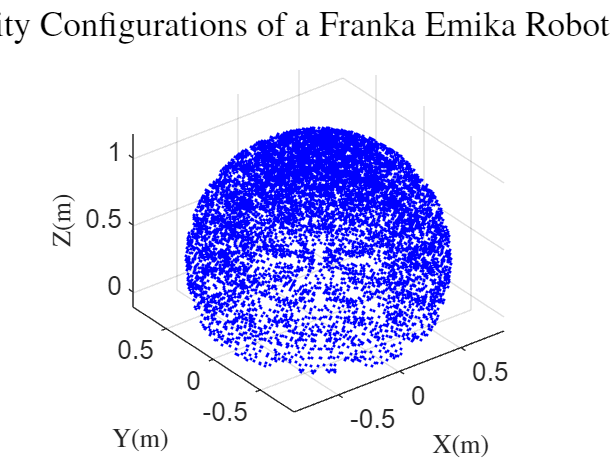

%distance = sqrt(X.^2 + Y.^2 + Z.^2); % compute distance from origin
%c = distance/max(distance); % normalize distances to [0,1]

scatter3(X, Y, Z, 'b.');
% colormap jet; % set the color map
% colorbar; % add a color bar to the plot
ax = gca;
ax.FontSize = 18;
xlabel('X(m)', 'FontSize', 18, 'Interpreter','latex');
ylabel('Y(m)', 'FontSize', 18, 'Interpreter','latex');
zlabel('Z(m)', 'FontSize', 18, 'Interpreter','latex');
title('Singularity Configurations of a Franka Emika Robot (Config 3)', 'FontSize', 24, 'Interpreter','latex');
axis equal;

%view(0,0);

#### Choose an arbitrary config to visualize

Q1_rndm = Q1(randi(numel(Q1)));
Q2_rndm = Q2(randi(numel(Q2)));
Q3_rndm = Q3(randi(numel(Q3)));
Q4_rndm = [th4];
Q5_rndm = [0];
Q6_rndm = Q6(randi(numel(Q6)));
Q7_rndm = Q7(randi(numel(Q7)));

thetas = unique(combvec(Q1_rndm, Q2_rndm, Q3_rndm, Q4_rndm, Q5_rndm, Q6_rndm, Q7_rndm)', 'rows');
thetas

thetas =    -2.8973    1.3711    0.9658   -0.4670         0    0.4014   -0.3219


Js =          0    0.2419   -0.9510   -0.2959   -0.8089   -0.2959    0.9431
         0   -0.9703   -0.2371    0.5124   -0.5833    0.5124    0.2907
    1.0000         0    0.1984   -0.8061   -0.0738   -0.8061   -0.1614
         0    0.3231    0.0789   -0.0639    0.2389    0.0644   -0.0306
         0    0.0805   -0.3167   -0.3398   -0.3468   -0.6299    0.1994
         0         0         0   -0.1925    0.1218   -0.4241    0.1803


ans = 5

2 linearly dependent joints:
  q6 depends on: q1 q2 q3 q4 
  q7 depends on: q1 q2 q3 q5 


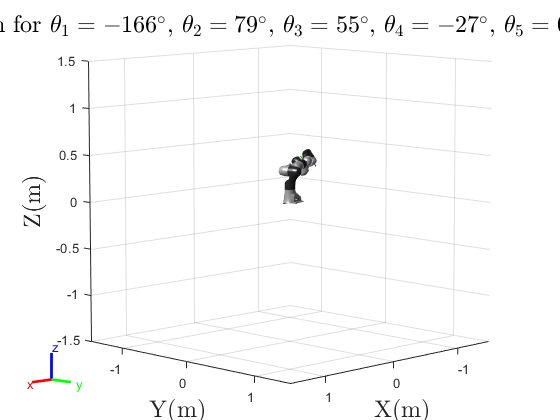


for theta = thetas'
    Js = J_SpaceForm(S, theta)
    rank(Js)
    jsingu(Js)
    robot = importrobot('Franka_Emika_Panda.urdf');
    robot.DataFormat = 'column';

    figure;

    str = "Singular Configuration for ";
    for i= 1:numel(theta)
        str = str + "$\theta_" + num2str (i) + "=" +num2str(round(rad2deg(theta(i)))) + "^ \circ $, ";
    end

    show(robot,theta,'Visuals','on','Frames','on');
    xlabel('X(m)', 'FontSize', 18, 'Interpreter','latex');
    ylabel('Y(m)', 'FontSize', 18, 'Interpreter','latex');
    zlabel('Z(m)', 'FontSize', 18, 'Interpreter','latex');

    title(str, 'FontSize', 18, 'Interpreter','latex');

end